# Solution to *The Cassini-Huygens Spacecraft III* exercise

## 1. Load the data and extract Year, Month, Day, X, Y, and Z

Load the file `cassiniData2.mat` and extract the columns Year, Month, Day, X, Y, and Z (columns 1-6, respectively) into separate variables.

load cassiniData2
Year = data(:,1);
Month = data(:,2);
Day = data(:,3);
X = data(:,4);
Y = data(:,5);
Z = data(:,6);

## 2. Compute the radius (distance from sun)

Using X, Y, and Z, compute the radius.

Radius = sqrt(X.^2 + Y.^2 + Z.^2);

## 3. Determine the dates on which the probe crossed each planet's orbit.

The orbit radii of the eight planets are given in the following table. Determine the dates on which the craft crossed each planet’s orbit.

Create a vector of the radii values.

planetRadii = [0.39,0.72,1.0,1.51,5,9.04,19.18,30.06];

Compute when the probe and each planet had the same distance from the sun.

Mercury_index = Radius == planetRadii(1);
Venus_index = Radius == planetRadii(2);
Earth_index = Radius == planetRadii(3);
Mars_index = Radius == planetRadii(4);
Jupiter_index = Radius == planetRadii(5);
Saturn_index = Radius == planetRadii(6);

Display when the craft crossed Mercury's orbit.

Mercury_Date = [Year(Mercury_index) Month(Mercury_index) Day(Mercury_index)]

Mercury_Date = 

Display when the craft crossed Venus's orbit.

Venus_Date = [Year(Venus_index) Month(Venus_index) Day(Venus_index)]

Venus_Date =         1998           2          27
        1998           2          28
        1999           6          25
        1999           6          26
        1999           6          27
        1999           6          28
        1999           7           2

Display when the craft crossed Earth's orbit.

Earth_Date = [Year(Earth_index) Month(Earth_index) Day(Earth_index)]

Earth_Date =         1997          10          17
        1997          10          18
        1997          10          19
        1997          10          20
        1997          10          21
        1997          11          21
        1997          11          22
        1997          11          23
        1997          11          24
        1997          11          26
        1997          11          27
        1997          11          28
        1997          11          29
        1999           5          13
        1999           8          17

Display when the craft crossed Mars's orbit.

Mars_Date = [Year(Mars_index) Month(Mars_index) Day(Mars_index)]

Mars_Date =         1998          10          14
        1998          10          15
        1999           1          29

Display when the craft crossed Jupiter's orbit.

Jupiter_Date = [Year(Jupiter_index) Month(Jupiter_index) Day(Jupiter_index)]

Jupiter_Date =         2000          12          28
        2000          12          29

Display when the craft crossed Saturn's orbit.

Saturn_Date = [Year(Saturn_index)  Month(Saturn_index) Day(Saturn_index)]

Saturn_Date =         2004           6          30
        2004           7           1

## 4. Plot the XY position for each year

Plot the X-Y position of the spacecraft for each year in a different color or style on the same plot.

Extract each year's data.

I1997 = (Year == 1997);
I1998 = (Year == 1998);
I1999 = (Year == 1999);
I2000 = (Year == 2000);
I2001 = (Year == 2001);
I2002 = (Year == 2002);
I2003 = (Year == 2003);
I2004 = (Year == 2004);

Create the figure and plot in different colors

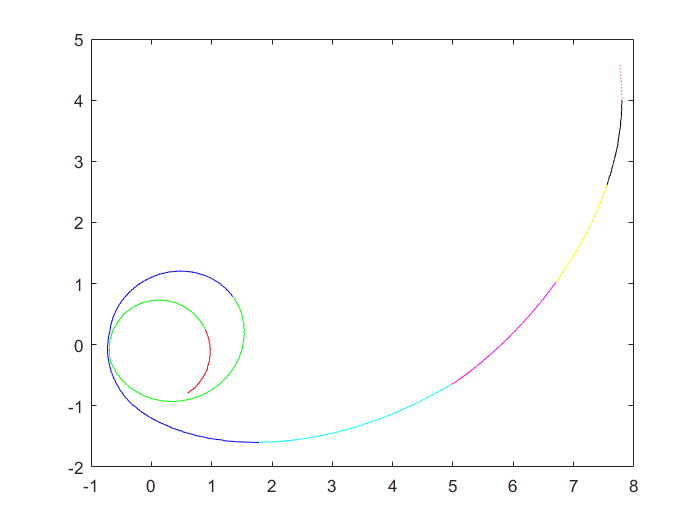

plot(X(I1997),Y(I1997),'r')
hold on
plot(X(I1998),Y(I1998),'g')
plot(X(I1999),Y(I1999),'b')
plot(X(I2000),Y(I2000),'c')
plot(X(I2001),Y(I2001),'m')
plot(X(I2002),Y(I2002),'y')
plot(X(I2003),Y(I2003),'k')
plot(X(I2004),Y(I2004),'r:')

## 4. Add in the orbits of Mercury, Venus, Earth, Mars, Jupiter, and Saturn

Add the orbits of Mercury, Venus, Earth, Mars, Jupiter, and Saturn.

Create a unit circle.

theta = linspace(0,2*pi,100);
xc = cos(theta);
yc = sin(theta);

Plot each planet's orbit as a dotted black line.

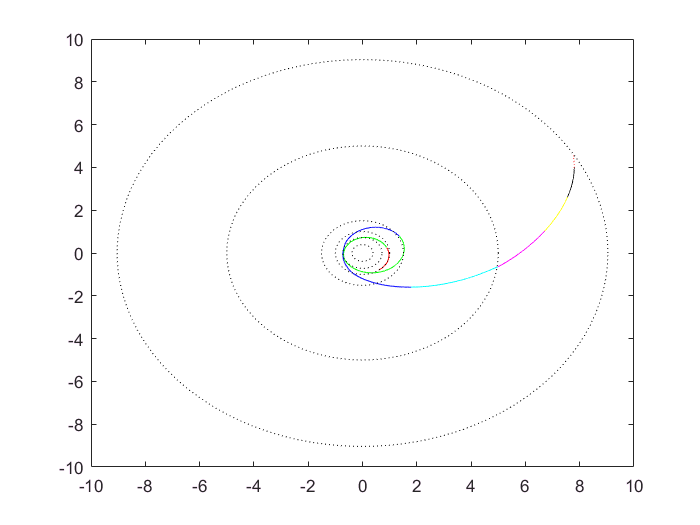

plot(planetRadii(1)*xc,planetRadii(1)*yc,'k:')
plot(planetRadii(2)*xc,planetRadii(2)*yc,'k:')
plot(planetRadii(3)*xc,planetRadii(3)*yc,'k:')
plot(planetRadii(4)*xc,planetRadii(4)*yc,'k:')
plot(planetRadii(5)*xc,planetRadii(5)*yc,'k:')
plot(planetRadii(6)*xc,planetRadii(6)*yc,'k:')
hold off